clc
clear
% path='\\sf3.bss.phy.private.cam.ac.uk\cicutagroup\yz655\modelling\circle_videos\pixel_videos_directioned_Iqtau\';
% filename='large_fx_0.02_fy_0.05_fxy_0_tauc_0_xc_0_yc_0_freq_0.4_gray_nonAvgIqtau_angle_Iqtau.mat';
path='\\sf3.bss.phy.private.cam.ac.uk\cicutagroup\yz655\real_videos_exp\water_closeup_cropped_Analysis\';
filename='19V_2023-02-22-132638-0000_nonAvgIqtau_angle_Iqtau.mat';
input=[path filename];
load(input)

angle_num=size(angle_Iqtau,1);
qVec=1:size(angle_Iqtau,2);
q_num=size(angle_Iqtau,2);
tVec=1:size(angle_Iqtau,3);
t_num=size(angle_Iqtau,3);

wavelength=1;
scale=1024;
q_max=500;
filename='5V_2023-02-22-132111-0000_nonAvgIqtau_angle_Iqtau.mat';
plotIq_all_dirc_all_tau(filename,path,wavelength,scale,q_max)

% clc
% clear
voltage=[];
q_peak=[];
q_avg=[];
q_std=[];
q_max=200;
q=2;
files = dir('*_nonAvgIqtau_angle_Iqtau.mat');
f=figure();
for file = files'
    load(file.name);
    angle_num=size(angle_Iqtau,1);
    qVec=1:size(angle_Iqtau,2);
    q_num=size(angle_Iqtau,2);
    tVec=1:size(angle_Iqtau,3);
    t_num=size(angle_Iqtau,3);


    
    x=tVec(:)/10;
    y=squeeze(sum(angle_Iqtau(:,q,:),1));
    plot(x,y)
    split_filename=split(file.name,'_');
    v=split_filename(1);
    v=v{1};
    v=sscanf(v,'%dV');
    voltage=[voltage v];
    angle_num=size(angle_Iqtau,1);
    qVec=1:size(angle_Iqtau,2);
    q_num=size(angle_Iqtau,2);
%     y=squeeze(sum(sum(angle_Iqtau(:,(1:q_max),:),1),3));
    y=squeeze(sum(sum(angle_Iqtau(:,:,:),1),3));

    [M,I]=max(y);
    q_peak=[q_peak I];


    avg=sum(qVec.*y)/sum(y);
    q_avg=[q_avg avg];
    q_std=[q_std std(qVec,y)];
    clf;
end

[voltage,I] = sort(voltage);
q_peak = q_peak(I);
q_avg = q_avg(I);
q_std = q_std(I);

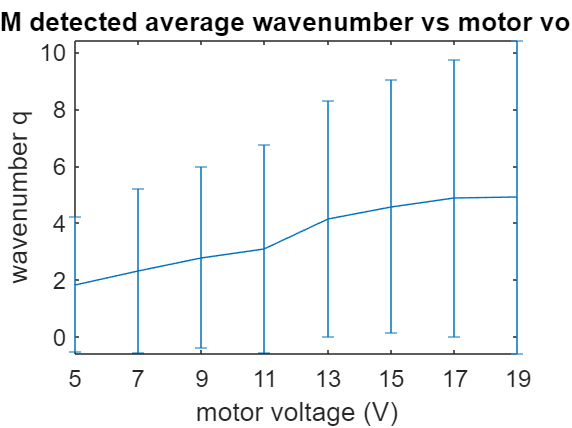

figure()
errorbar(voltage,q_avg,q_std);
xlim([5 19])
xticks([5 7 9 11 13 15 17 19])
xlabel('motor voltage (V)')
ylabel('wavenumber q')
title('DDM detected average wavenumber vs motor voltage')
set(gca,'fontsize', 12);

figure()
q_avg_united = q_avg/1024*128.386 % (cm^-1)

q_avg_united =     0.2316    0.2919    0.3505    0.3893    0.5214    0.5741    0.6115    0.6159


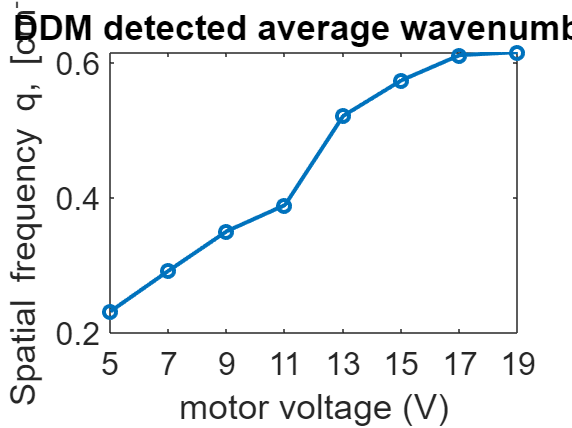

plot(voltage,q_avg_united,'-o',LineWidth=2);
xlim([5 19])
xticks([5 7 9 11 13 15 17 19])
xlabel('motor voltage (V)')
ylabel('Spatial frequency q, [cm^{-1}]','Interpreter','tex')
title('DDM detected average wavenumber')
set(gca,'fontsize', 16);

figure()
freq=[7 9 12 15 18 20 23 25];
video_length=13.1;
freq=freq/video_length;
q_avg_united = q_avg/1024*128.386 % (cm^-1)

q_avg_united =     0.3514    0.3760    0.4443    0.5719    0.5450    0.5681    0.6424    0.6296


plot(voltage,q_avg_united,'o',LineWidth=2);

Error using plot
Invalid data argument.



% xlim([5 19])
% 5V: 7
% 7V: 9
% 9V: 12
% 11V: 15, 1.1450 Hz
% 13V: 18, 1.3740
% 15V: 20, 1.5267 Hz
% 17V: 23
% 19V: 25
% xticks([5 7 9 11 13 15 17 19])
xlabel('Motor frequency (Hz)')
ylabel('Average spatial frequency q_{avg}, [cm^{-1}]','Interpreter','tex')
% title('DDM detected average wavenumber')
set(gca,'fontsize', 16);

figure()
[voltage,I] = sort(voltage);
q_peak = q_peak(I);

plot(voltage,q_peak,'-o',LineWidth=2)
xlim([5 19])
xticks([5 7 9 11 13 15 17 19])
xlabel('motor voltage (V)')
ylabel('wavenumber q')
title('DDM detected wavenumber vs motor voltage')
set(gca,'fontsize', 12);

wavelength=1;
scale=1024;
q_max=500;
files = natsortfiles(dir('*_nonAvgIqtau_angle_Iqtau.mat'));

Unrecognized function or variable 'natsortfiles'.

f=figure();
voltage=[];
% [distance_map, dist_counts] = create_distance_map(scale);
for file = files'   
%     plotIq_all_dirc_all_tau(file.name,path,wavelength,scale,q_max);

    load(file.name);
    angle_num=size(angle_Iqtau,1);
    qVec=1:size(angle_Iqtau,2);
    q_num=size(angle_Iqtau,2);
    tVec=1:size(angle_Iqtau,3);
    t_num=size(angle_Iqtau,3);
  
    y=sum(sum(angle_Iqtau(1:16,(1:q_max),:),1),3);
%     y_avg=y(:)./dist_counts(1:q_max); 
    semilogx(qVec(1:q_max),squeeze(y),"LineWidth",1)
    hold on

    
    split_filename=split(file.name,'_');
    v=split_filename(1);
%     v=v{1};
    voltage=[voltage v];
    
end

%     xticks([0 0.001 0.01 0.1])
set(gca,'fontsize', 12); 
%     xlabel('q, [pixel^{-1}]')
legend(voltage);
xlabel('q, [wavenumber]')
ylabel('I(q)')
title(['Sum of all directions, all taus'])

wavelength=1;
scale=1024;
q_max=723;
freq=[7 9 12 15 18 20 23 25];
video_length=13.1;
freq=freq/video_length;
files = natsortfiles(dir('*_nonAvgIqtau_angle_Iqtau.mat'));
f=figure();
voltage=[];
q_peak=[];
q_avg=[];
q_std=[];
count = 1;
for file = files'   
%     plotIq_all_dirc_all_tau(file.name,path,wavelength,scale,q_max);
    disp(file.name);
    current_freq = freq(count);
    current_tau = round(1/current_freq*0.5*10);

    load(file.name);
    angle_num=size(angle_Iqtau,1);
    qVec=1:size(angle_Iqtau,2);
    q_num=size(angle_Iqtau,2);
    tVec=1:size(angle_Iqtau,3);
    t_num=size(angle_Iqtau,3);
  
%     y=sum(sum(angle_Iqtau(1:16,(1:q_max),:),1),3);
%     y=sum(angle_Iqtau(1:16,(1:q_max),current_tau),1);
    y=sum(angle_Iqtau(3:4,(1:q_max),current_tau),1);
%     y_avg=y(:)./dist_counts(1:q_max); 
    semilogx(qVec(1:q_max),squeeze(y),"LineWidth",1)
    hold on

    
    split_filename=split(file.name,'_');
    v=split_filename(1);
%     v=v{1};
    voltage=[voltage v];

    [M,I]=max(y);
    q_peak=[q_peak I];


    avg=sum(qVec(1:q_max).*y)/sum(y);
    q_avg=[q_avg avg];
    q_std=[q_std std(qVec(1:q_max),y)];
    
end

5V_2023-02-22-132111-0000_nonAvgIqtau_angle_Iqtau.mat
7V_2023-02-22-132146-0000_nonAvgIqtau_angle_Iqtau.mat
9V_2023-02-22-132213-0000_nonAvgIqtau_angle_Iqtau.mat
11V_2023-02-22-132410-0000_nonAvgIqtau_angle_Iqtau.mat
13V_2023-02-22-132438-0000_nonAvgIqtau_angle_Iqtau.mat
15V_2023-02-22-132509-0000_nonAvgIqtau_angle_Iqtau.mat
17V_2023-02-22-132606-0000_nonAvgIqtau_angle_Iqtau.mat
19V_2023-02-22-132638-0000_nonAvgIqtau_angle_Iqtau.mat


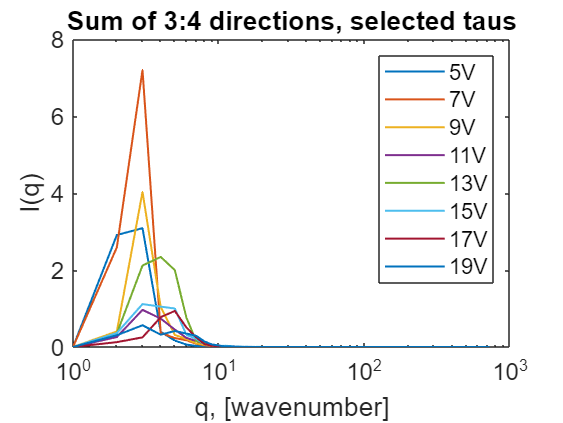


%     xticks([0 0.001 0.01 0.1])
set(gca,'fontsize', 12); 
%     xlabel('q, [pixel^{-1}]')
legend(voltage);
xlabel('q, [wavenumber]')
ylabel('I(q)')
title(['Sum of 3:4 directions, selected taus'])

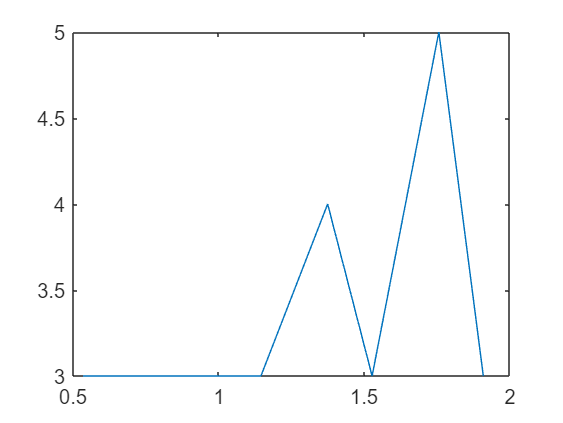

figure()
plot(freq,q_peak)

figure()
freq=[7 9 12 15 18 20 23 25];
video_length=13.1;
freq=freq/video_length;
q_avg_united = q_avg/1024*128.386 % (cm^-1)

q_avg_united =     0.2316    0.2919    0.3505    0.3893    0.5214    0.5741    0.6115    0.6159


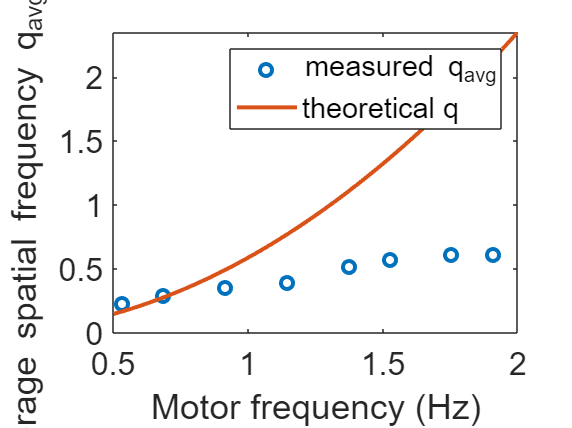

% errorbar(freq,q_avg_united,q_std);
plot(freq,q_avg_united,'o',LineWidth=2);
hold on
f_list = 0.5:0.01:2;
rho_1=998; % kg/m^3
rho_2=870; % kg/m^3
g=9.8; % m/s^2
g_prime = (rho_1-rho_2)/(rho_1+rho_2)*g;
% q_theory= 2*pi*f_list.*f_list/g_prime;
q_theory= 2*pi*2*pi*f_list.*f_list/g_prime;
% 1m=100cm, 1m^-1=0.01cm^-1
q_theory= 0.01*q_theory;
plot(f_list,q_theory,LineWidth=2)
legend('measured q_{avg}','theoretical q','Interpreter','tex')


% xlim([5 19])
% 5V: 7
% 7V: 9
% 9V: 12
% 11V: 15, 1.1450 Hz
% 13V: 18, 1.3740
% 15V: 20, 1.5267 Hz
% 17V: 23
% 19V: 25
% xticks([5 7 9 11 13 15 17 19])
xlabel('Motor frequency (Hz)')
ylabel('Average spatial frequency q_{avg}, [cm^{-1}]','Interpreter','tex')
% title('DDM detected average wavenumber')
set(gca,'fontsize', 16);

figure()
freq=[7 9 12 15 18 20 23 25];
video_length=13.1;
freq=freq/video_length;
q_avg_united = q_avg/1024*128.386 % (cm^-1)

Unrecognized function or variable 'q_avg'.

% errorbar(freq,q_avg_united,q_std);
semilogx(freq,q_avg_united,'o',LineWidth=2);
hold on
f_list = 0.5:0.01:2;
rho_1=998; % kg/m^3
rho_2=870; % kg/m^3
g=9.8; % m/s^2
g_prime = (rho_1-rho_2)/(rho_1+rho_2)*g;
q_theory= 2*pi*f_list.*f_list/g_prime;
% 1m=100cm, 1m^-1=0.01cm^-1
q_theory= 0.01*q_theory;
semilogx(f_list,q_theory,LineWidth=2)
legend('measured q_{avg}','theoretical q_{avg}','Interpreter','tex')


% xlim([5 19])
% 5V: 7
% 7V: 9
% 9V: 12
% 11V: 15, 1.1450 Hz
% 13V: 18, 1.3740
% 15V: 20, 1.5267 Hz
% 17V: 23
% 19V: 25
% xticks([5 7 9 11 13 15 17 19])
xlabel('Motor frequency (Hz)')
ylabel('Average spatial frequency q_{avg}, [cm^{-1}]','Interpreter','tex')
% title('DDM detected average wavenumber')
set(gca,'fontsize', 16);

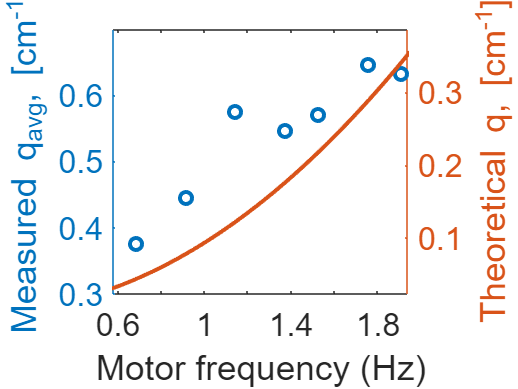

figure()
freq=[7 9 12 15 18 20 23 25];
video_length=13.1;
freq=freq/video_length;
q_std_united = q_std/1024*128.386;
q_avg_united = q_avg/1024*128.386; % (cm^-1)
yyaxis left
plot(freq,q_avg_united,'o',LineWidth=2);
% errorbar(freq,q_avg_united,q_std);
ylabel('Measured q_{avg}, [cm^{-1}]','Interpreter','tex')

f_list = 0.5:0.01:2;
rho_1=998; % kg/m^3
rho_2=870; % kg/m^3
g=9.8; % m/s^2
g_prime = (rho_1-rho_2)/(rho_1+rho_2)*g;
q_theory= 2*pi*f_list.*f_list/g_prime;
% 1m=100cm, 1m^-1=0.01cm^-1
q_theory= 0.01*q_theory;

yyaxis right
plot(f_list,q_theory,LineWidth=2)
ylabel('Theoretical q, [cm^{-1}]','Interpreter','tex')
% legend('measured q_{avg}','theoretical q_{avg}','Interpreter','tex')

xlabel('Motor frequency (Hz)')
% ylabel('Average spatial frequency q_{avg}, [cm^{-1}]','Interpreter','tex')
% title('DDM detected average wavenumber')
set(gca,'fontsize', 16);

freq=[7 9 12 15 18 20 23 25];
video_length=13.1;
freq=freq/video_length;
frame_rate=10;
tau_list=1./freq*frame_rate;

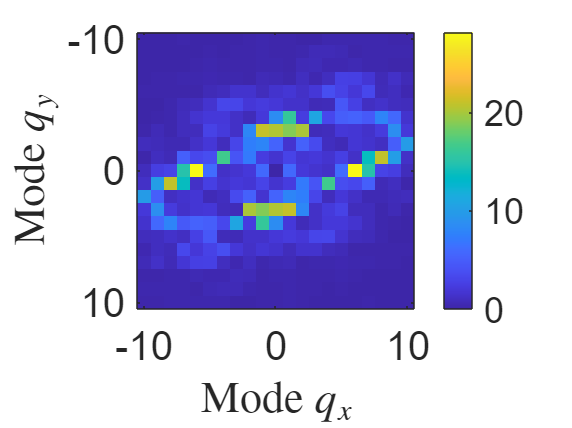


wavelength=1;
scale=1024;
q_max=500;
files = natsortfiles(dir('*_nonAvgIqtau_angle_Iqtau.mat'));
f=figure();
voltage=[];
[distance_map, dist_counts] = create_distance_map(scale);

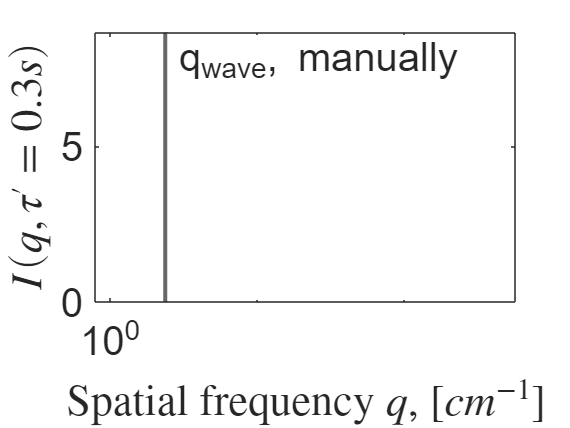

for file = files'   
%     plotIq_all_dirc_all_tau(file.name,path,wavelength,scale,q_max);

    load(file.name);
    angle_num=size(angle_Iqtau,1);
    qVec=1:size(angle_Iqtau,2);
    q_num=size(angle_Iqtau,2);

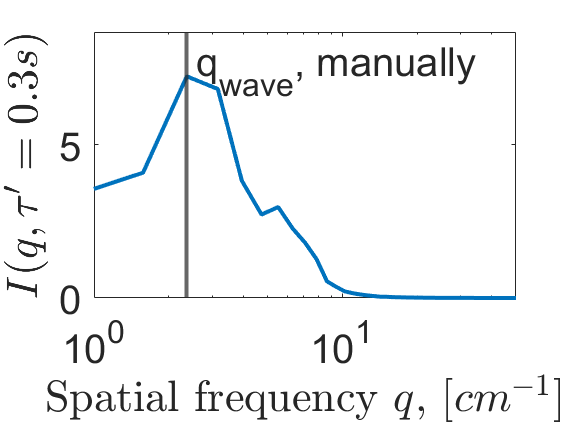

    tVec=1:size(angle_Iqtau,3);
    t_num=size(angle_Iqtau,3);
  

    y=sum(sum(angle_Iqtau(1:16,(1:q_max),:),1),3);
%     y_avg=y(:)./dist_counts(1:q_max); 
    semilogx(qVec(1:q_max),squeeze(y),"LineWidth",1)
    hold on

    
    split_filename=split(file.name,'_');
    v=split_filename(1);
%     v=v{1};
    voltage=[voltage v];
    
end

%     xticks([0 0.001 0.01 0.1])
set(gca,'fontsize', 12); 
%     xlabel('q, [pixel^{-1}]')
legend(voltage);
xlabel('q, [wavenumber]')
ylabel('I(q)')
title(['Sum of all directions, all taus'])

voltage
q_peak

path='\\sf3.bss.phy.private.cam.ac.uk\cicutagroup\yz655\real_videos_exp\water_closeup_cropped_Analysis\';
filename='19V_2023-02-22-132638-0000_nonAvgIqtau.mat';
input=[path filename];
load(input);
theta=0;
wavenumber=3;
scale=1024;
q_range=10;
tau=3;
plotFFTdifference(nonAvgIqtau,theta,wavenumber,scale,q_range,tau,path)

tau=3;
scale=1024;
wavenumber=3;
fps=10;
q_max=q_num;
plotIq_all_dirc_selected_tau(angle_Iqtau,tau,path,wavenumber,scale,q_max,fps)

xlim([1 50])
xticks([10^(0) 10^1])

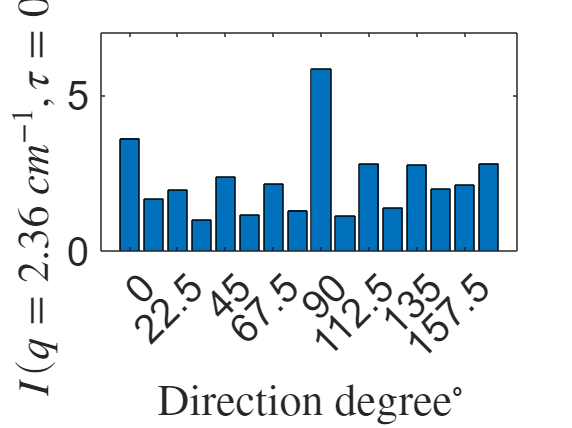

clf
t=10;

q_max=100;
for i=1:angle_num/4
    y=sum(angle_Iqtau(i:i+3,1:q_max,t));
    plot(qVec(1:q_max),y)
    hold on
end
legend
xlabel('q')
ylabel('Iqtau')
title('Iqtau-q in different directions')

figure()
clf
t=10;
q_max=100;
for i=1:angle_num
    y=angle_Iqtau(i,1:q_max,t);
    plot(qVec(1:q_max),y)
    hold on
end
legend
xlabel('q')
ylabel('Iqtau')
title('Iqtau-q in different directions')

q=3;
tau=3;
fps=18.987;
scale=1024;
figure()
y=squeeze(sum(sum(angle_Iqtau(:,1:10,tau),2),3));
bar(1:angle_num,y);
xticks(1:2:angle_num);
xticklabels(round(((1:2:angle_num)-1)*180/16,2));
ylim([0 1.2*max(y)])
xlabel('Direction degree$^{\circ}$','Interpreter','latex')
ylabel(['$I(q=$' num2str(round(q*2*pi*128.386/scale,2)) ' $cm^{-1},\tau=$' num2str(tau/fps) '$s)$'],'Interpreter','latex')
% title('Sum of Iqtau in 16 directions')
set(gca,'fontsize', 20);
ax=gca;
ax.YAxis.FontSize = 16;
ax.XAxis.FontSize = 16;

figure()
% q=3;
q=3;

f =      General model:
     f(x) = fit_function(x,A,v,tau_c,B)
     Coefficients (with 95% confidence bounds):
       A =      0.3647  (-0.7486, 1.478)
       B =       4.598  (4.109, 5.086)
       tau_c =  -3.287e+05  (-8.451e+10, 8.451e+10)
       v =       3.987  (3.927, 4.047)

y=squeeze(sum(sum(angle_Iqtau(:,q,:),2),3));
bar(1:angle_num,y);
xticks(1:angle_num)
ylim([0 1.2*max(y)])
xlabel('direction *pi/16')
ylabel('sum of Iqtau')
title(['Sum of Iqtau in 16 directions for q=' num2str(q)])
set(gca,'fontsize', 16);

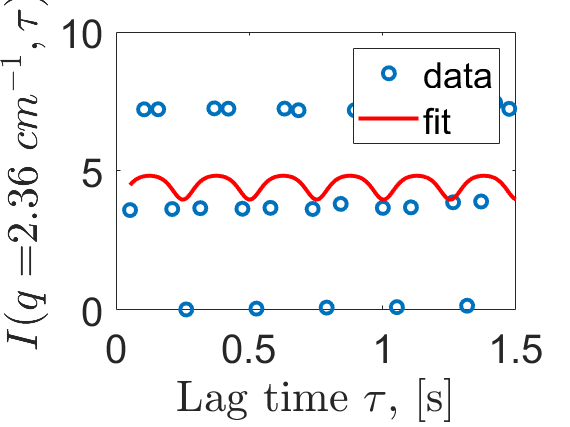

figure()

q_max=20;
imagesc(squeeze(sum(angle_Iqtau(:,1:q_max,:),1)));
xticks([50 100 150])
xticklabels({'5','10','15'})
xlabel('lag time tau(s)')
ylabel('wavenumber q')
title('I(q,tau) heatmap')
colorbar;
set(gca,'fontsize', 12);

figure()
q=2;
plot(tVec/10,squeeze(sum(angle_Iqtau(:,q,:),1)),'-o')
% ylim([0 0.02])
xlim([0 3])
xlabel('lag time tau(s)')
ylabel(['I(q=' num2str(q) ',tau)'])
title(['I(q=' num2str(q) ',tau)-tau plot'])
set(gca,'fontsize', 12);

q=3;
fps=18.987;
x=tVec(:)/fps;
y=squeeze(sum(angle_Iqtau(:,q,:),1));
% exclude=[1 2];
ft = fittype( 'fit_function(x,A,v,tau_c,B)' );
% StartPoint order: A,B,tau_c,v
f = fit( x, y, ft, 'StartPoint', [200, 4, -1000, 4])
h=plot( f, x, y ,"o"); 
h(1).LineWidth=2;
h(2).LineWidth=2;
xlim([0 1.5])
ylim([0 10])
xlabel('Lag time $\tau$, [s]','Interpreter','latex')
ylabel(['$I(q=$' num2str(round(q*2*pi*128.386/scale,2)) ' $cm^{-1},\tau)$'],'Interpreter','latex')
legend('data','fit')
set(gca,'fontsize', 20);

q=3;
figure();
bar(1:angle_num,squeeze(sum(angle_Iqtau(:,q,:),3)));
xticks(1:angle_num)
xlabel('direction *pi/16')
ylabel('sum of Iqtau')
title(['Sum of Iqtau(q=' num2str(q) ') in 16 directions'])

% x_label=(0:angle_num-1)*180/angle_num
% strsplit(num2str(round(x_label)))
% set(gca,'xticklabel',{'40 feet','60 feet','120 feet'})

figure()
bar(1:angle_num,squeeze(sum(sum(angle_Iqtau,2),3)));

figure()
plot(1:t_num,squeeze(angle_Iqtau(1,1,:)))

imagesc(log(squeeze(sum(angle_Iqtau(5,1:10,:),1))))

% filename='large_fx_0.02_fy_0.02_fxy_0_tauc_0_xc_0_yc_0_freq_0.4_gray_nonAvgIqtau_angle_Iqtau.mat';
% input=[path filename];
% angle_Iqtau0202=load(input);
% 
% filename='large_fx_0.02_fy_0.1_fxy_0_tauc_0_xc_0_yc_0_freq_0.4_gray_nonAvgIqtau_angle_Iqtau.mat';
% input=[path filename];
% angle_Iqtau0210=load(input);
% 
% filename='large_fx_0.02_fy_0_fxy_0_tauc_0_xc_0_yc_0_freq_0.4_gray_nonAvgIqtau_angle_Iqtau.mat';
% input=[path filename];
% angle_Iqtau0200=load(input);

% filename='large_fx_0_fy_0_fxy_0_tauc_0_xc_0_yc_0_freq_0.4_gray_nonAvgIqtau_angle_Iqtau.mat';
% input=[path filename];
% angle_Iqtau0000=load(input);

q_max=50;
figure()
z=sum(angle_Iqtau(1:16,(1:q_max),:),1);
plot3(repmat((qVec(1:q_max))',1,t_num),repmat((tVec),q_max,1),squeeze(z))
% xlim([0 200])
xlabel('q')
ylabel('tau')
zlabel('Iqtau')
title('Sum of all directions')

num_of_wave_on_diagonal=1.41;
scale=1024;
q_max=200;
plotIq(filename,path,num_of_wave_on_diagonal,scale,q_max)


path='\\sf3.bss.phy.private.cam.ac.uk\cicutagroup\yz655\modelling\circle_videos\paper_videos\plots\'

clc
filename='large_fx_0.1_fy_0.1_fxy_0_tauc_0_xc_0_yc_0_freq_0.3_gray_nonAvgIqtau_angle_Iqtau.mat';
num_of_wave_on_diagonal=6;
scale=1024;
q_max=200;
plotIq(filename,path,num_of_wave_on_diagonal,scale,q_max)

clc
filename='large_fx_0.2_fy_0.2_fxy_0_tauc_0_xc_0_yc_0_freq_0.3_gray_nonAvgIqtau_angle_Iqtau.mat';
num_of_wave_on_diagonal=12;
scale=1024;
q_max=200;
plotIq(filename,path,num_of_wave_on_diagonal,scale,q_max)

clc
filename='large_fx_0.15_fy_0.15_fxy_0_tauc_0_xc_0_yc_0_freq_0.3_gray_nonAvgIqtau_angle_Iqtau.mat';
num_of_wave_on_diagonal=8.5;
scale=1024;
q_max=200;
plotIq(filename,path,num_of_wave_on_diagonal,scale,q_max)

clc
filename='large_fx_0.05_fy_0.05_fxy_0_tauc_0_xc_0_yc_0_freq_0.3_gray_nonAvgIqtau_angle_Iqtau.mat';
num_of_wave_on_diagonal=3;
scale=1024;
q_max=200;
plotIq(filename,path,num_of_wave_on_diagonal,scale,q_max)

clc
filename='large_fx_0_fy_0_fxy_0_tauc_0_xc_0_yc_0_freq_0.2_gray_nonAvgIqtau_angle_Iqtau.mat';
num_of_wave_on_diagonal=23;
scale=1024;
q_max=200;
plotIq(filename,path,num_of_wave_on_diagonal,scale,q_max)

clc
% filename='large_theta_-2.618(rad)_fx_-0.1_fy_-0.173_fxy_0_tauc_0_xc_0_yc_0_freq_0.3_gray_nonAvgIqtau_angle_Iqtau.mat';
filename='large_theta_-3.1416(rad)_fx_-2.45e-17_fy_-0.2_fxy_0_tauc_0_xc_0_yc_0_freq_0.3_gray_nonAvgIqtau_angle_Iqtau.mat'
load(filename);
num_of_wave_on_diagonal=8;
scale=1024;
q_max=200;
plotIq(filename,path,num_of_wave_on_diagonal,scale,q_max)

filename='large_fx_0.1_fy_0.1_fxy_0_tauc_0_xc_0_yc_0_freq_0.2_gray_nonAvgIqtau_angle_Iqtau.mat';
load(filename);
num_of_wave_on_diagonal=3;
scale=1024;
q_max=200;
plotIq(filename,path,num_of_wave_on_diagonal,scale,q_max)

filename='large_fx_0.1_fy_0.1_fxy_0_tauc_0_xc_0_yc_0_freq_0.2_gray_nonAvgIqtau_angle_Iqtau.mat';
load(filename);
num_of_wave_on_diagonal=3;
scale=1024;
q_max=200;
plotIq(filename,path,num_of_wave_on_diagonal,scale,q_max)

q_max=100;
figure()
y=sum(sum(angle_Iqtau(1:16,(1:q_max),:),1),3)...
    -sum(sum(angle_Iqtau0000.angle_Iqtau(1:16,(1:q_max),:),1),3);
plot(qVec(1:q_max),squeeze(y))
% xlim([0 200])
xlabel('q')
ylabel('Iqtau')
title('Sum of all directions, all taus')

figure()
t=30;
q_max_to_include=3;
q=17; % peak ]
subplot(4,1,1)
plot(1:angle_num,sum(angle_Iqtau0200.angle_Iqtau(:,1:q_max_to_include,t),2))
xlabel('direction')
ylabel('I(q=17,t=16)')
title('f_x=0.02, f_y=0')
subplot(4,1,2)
plot(1:angle_num,sum(angle_Iqtau0202.angle_Iqtau(:,1:q_max_to_include,t),2))
title('f_x=0.02, f_y=0.02')
subplot(4,1,3)
plot(1:angle_num,sum(angle_Iqtau(:,1:q_max_to_include,t),2))
title('f_x=0.02, f_y=0.05')
subplot(4,1,4)
plot(1:angle_num,sum(angle_Iqtau0210.angle_Iqtau(:,1:q_max_to_include,t),2))
title('f_x=0.02, f_y=0.10')
sgtitle('I in 16 different directions')

d=15;
q=2;
tVec=1:50;
fig=figure();
subplot(3,1,1)
plot(tVec/10,squeeze(angle_Iqtau02.angle_Iqtau(d,q,:)))
title('f_t=0.2Hz')
ylabel('I(q=2,t)')
subplot(3,1,2)
plot(tVec/10,squeeze(angle_Iqtau(d,q,:)))
title('f_t=0.4Hz')
ylabel('I(q=2,t)')
subplot(3,1,3)
plot(tVec/10,squeeze(angle_Iqtau06.angle_Iqtau(d,q,:)))
title('f_t=0.6Hz')
xlabel('time (s)')
ylabel('I(q=2,t)')
sgtitle('I(q=2,t)-t plot for different time frequencies')

saveas(fig,'I(q=2,t)-t plot for different time frequencies.png')


filename='large_fx_0.02_fy_0.05_fxy_0_tauc_0_xc_0_yc_0_freq_0.2_gray_nonAvgIqtau_angle_Iqtau.mat';
input=[path filename];
angle_Iqtau02=load(input);

filename='large_fx_0.02_fy_0.05_fxy_0_tauc_0_xc_0_yc_0_freq_0.6_gray_nonAvgIqtau_angle_Iqtau.mat';
input=[path filename];
angle_Iqtau06=load(input);

surf(repmat((1:598)',1,50),repmat((1:50),598,1),squeeze(angle_Iqtau(1,:,:)))

plot3(repmat((1:598)',1,50),repmat((1:50),598,1),squeeze(angle_Iqtau(1,:,:)))
xlabel('q')
ylabel('tau')
zlabel('Iqtau')
title('Direction 1')

plot3(repmat((1:598)',1,50),repmat((1:50),598,1),squeeze(angle_Iqtau(2,:,:)))
xlabel('q')
ylabel('tau')
zlabel('Iqtau')
title('Direction 2')

plot3(repmat((1:598)',1,50),repmat((1:50),598,1),squeeze(angle_Iqtau(3,:,:)))
xlabel('q')
ylabel('tau')
zlabel('Iqtau')
title('Direction 3')

plot3(repmat((1:598)',1,50),repmat((1:50),598,1),squeeze(angle_Iqtau(4,:,:)))
xlabel('q')
ylabel('tau')
zlabel('Iqtau')
title('Direction 4')

plot(1:50,squeeze(angle_Iqtau(1,30,:)))

scale=846;
plot3(repmat((1-scale/2:scale/2)',1,scale),repmat((1-scale/2:scale/2),scale,1),fftshift(squeeze(nonAvgIqtau(:,:,10))))
xlabel('q_x')
ylabel('q_y')
zlabel('FFT difference')
title('FFT difference at tau=10s')

